# Sesion 3

Jesus Molina Roldán

Victor Vidal Rojas Condori

## Filtro por suavizado

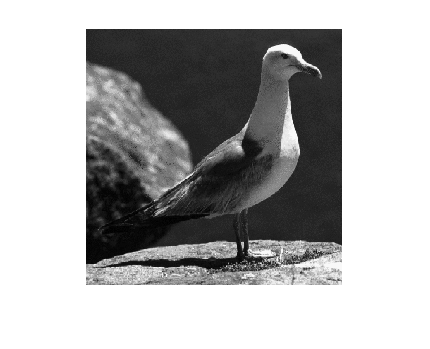

a = imread('gull.tif');
imshow(a)

%fspecial devuelve un filtro con la matriz que le pasemos.(Filtro
%gaussiano)

Le añadimos ruido a la imagen para poder trabajar con ella:

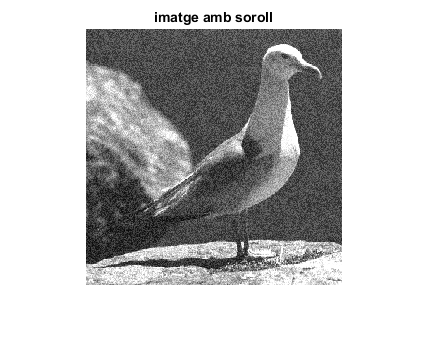

soroll = randi(70,256,'uint8');
aSoroll = a + soroll;
%aSoroll = mod(aSoroll,256) Si el tipo no fuera uint8
imshow(aSoroll)
title('imatge amb soroll')

Probamos el filtro gausiano

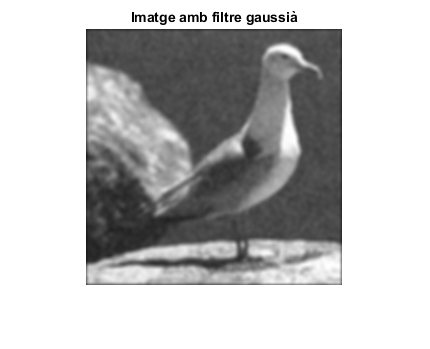

% 7 es el tamaño , 2 es la desviacion estandar
h = fspecial('gaussian', 7, 2);
res1 = imfilter(aSoroll,h,'conv');
imshow(res1),title('Imatge amb filtre gaussià')

Añadimos ruido 'salt & pepper' y probamos filtro gaussiano

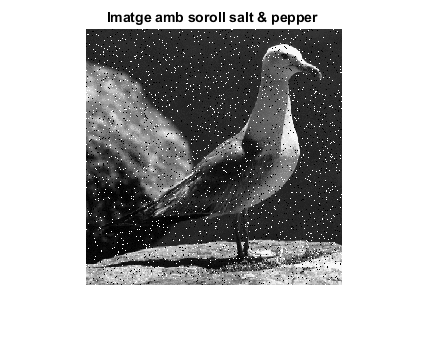

res2 = imnoise(a,'salt & pepper');
imshow(res2), title('Imatge amb soroll salt & pepper ')

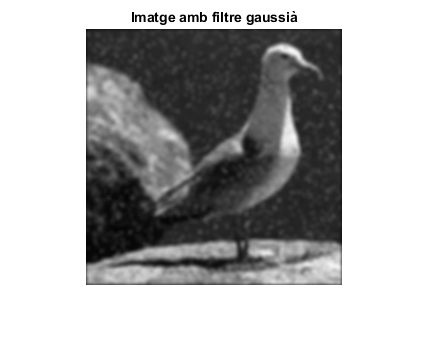

res3 = imfilter(res2,h,'conv');
imshow(res3), title('Imatge amb filtre gaussià')

Probamos el filtro no lineal (Mediana)

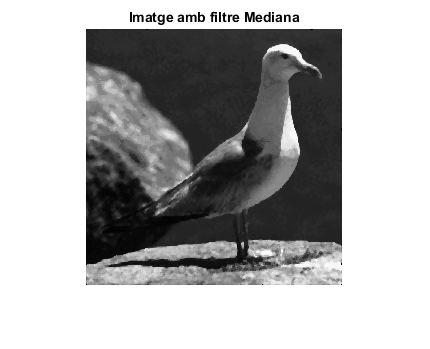

res4 = medfilt2(res2,[5 5]);
imshow(res4),title('Imatge amb filtre Mediana')

## Detección de contornos

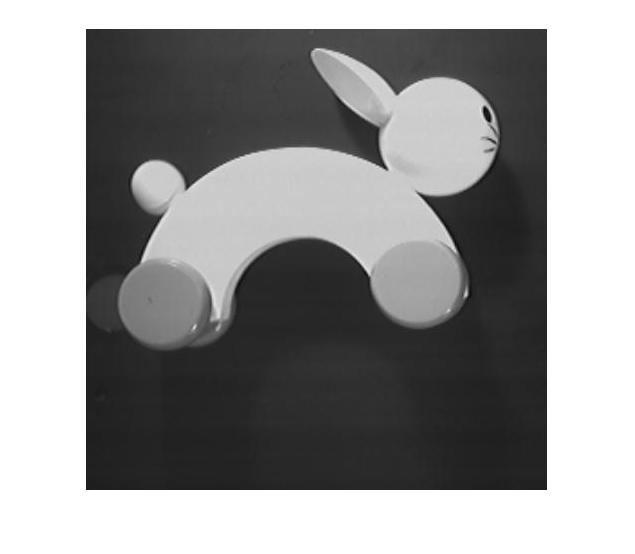

im = imread('rabbit.jpg');
imshow(im)

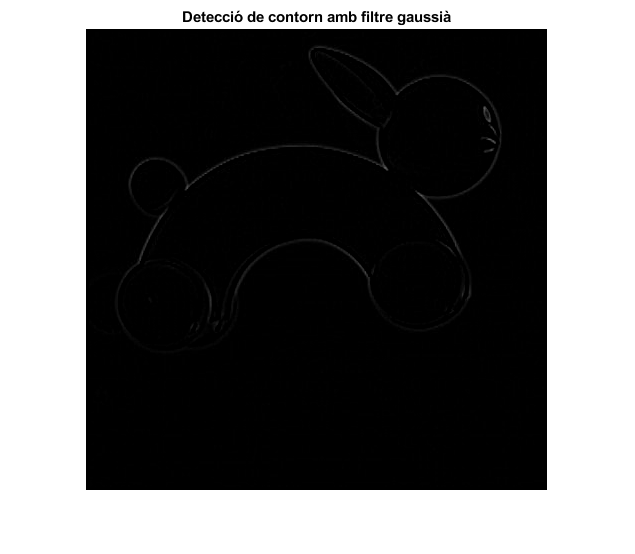

h = fspecial('gaussian', 7, 5);
imAux = imfilter(im,h);
res = imAux-im;
imshow(res),title('Detecció de contorn amb filtre gaussià')

Problema

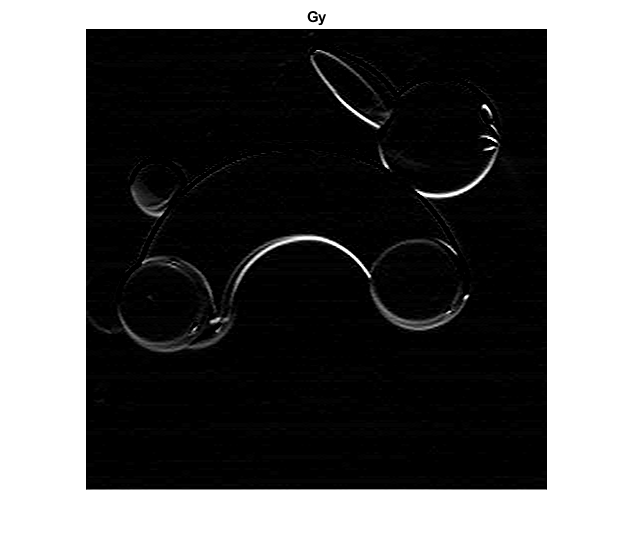

h = fspecial('Sobel');
gy = imfilter(im,h);
imshow(gy,[]), title('Gy')

## Solucionar problema

Operador Sobel

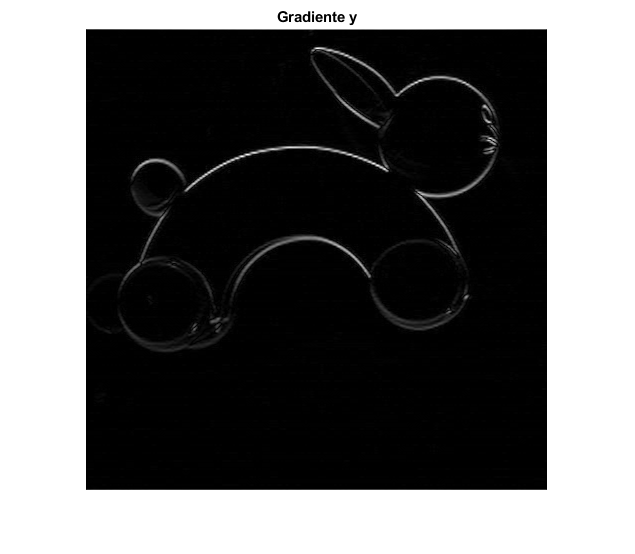

h = fspecial('Sobel');
h = h/4;
gy = imfilter(double(im),h);
imshow(abs(gy),[]), title('Gradiente y')

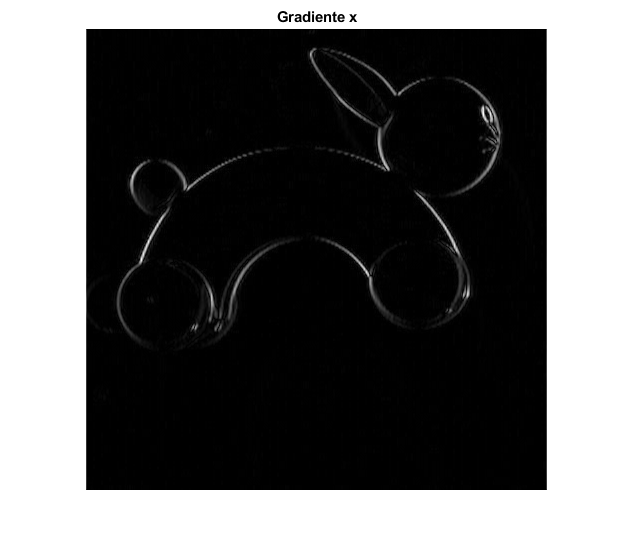

gx = imfilter(double(im),h');
imshow(abs(gx),[]), title('Gradiente x')

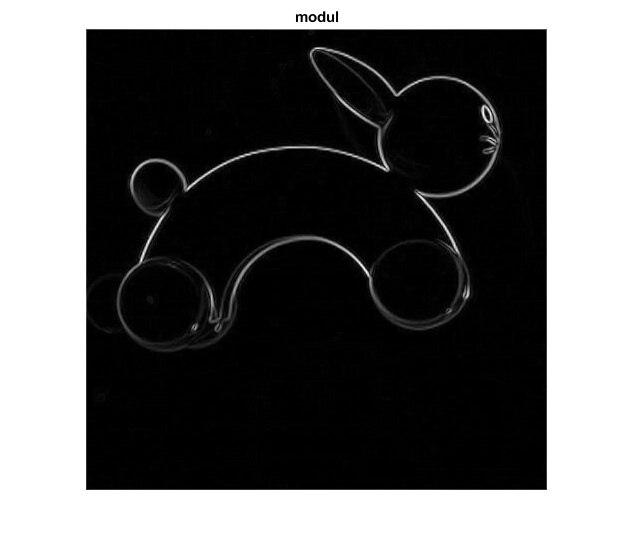

mod = sqrt(gx.^2+gy.^2);
figure,imshow(mod,[]), title('modul')

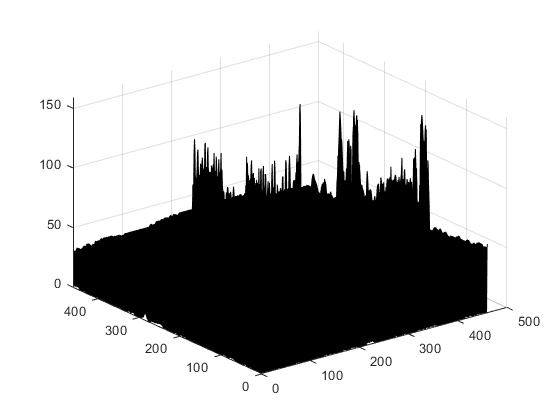

figure,surf(mod)

Filtro Laplaciano

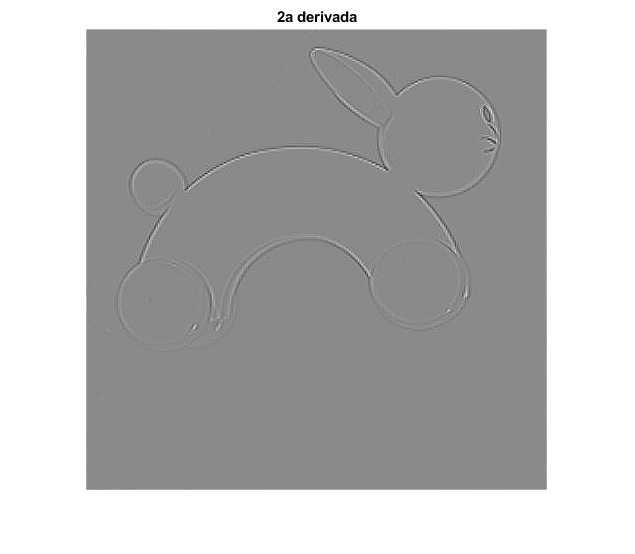

h = [0 -1 0; -1 4 -1; 0 -1 0];
lap = imfilter(double(im),h);
figure,imshow(lap,[]),title('2a derivada')

Operador de Canny-> Sigue la direccion del gradiente

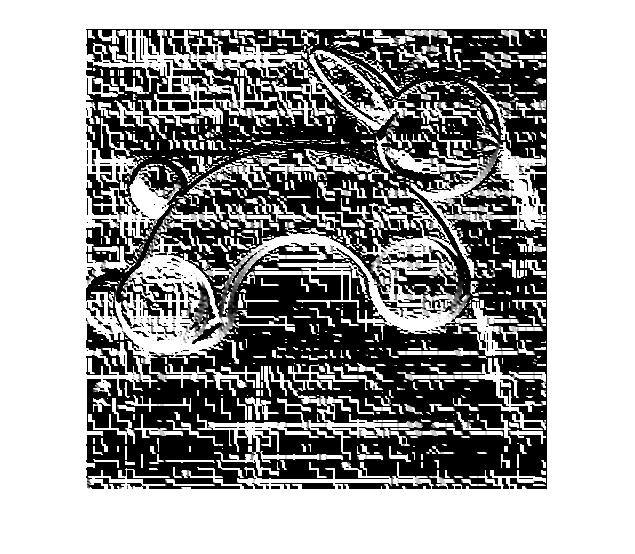

dir = atan2(gy,gx);
imshow(dir);

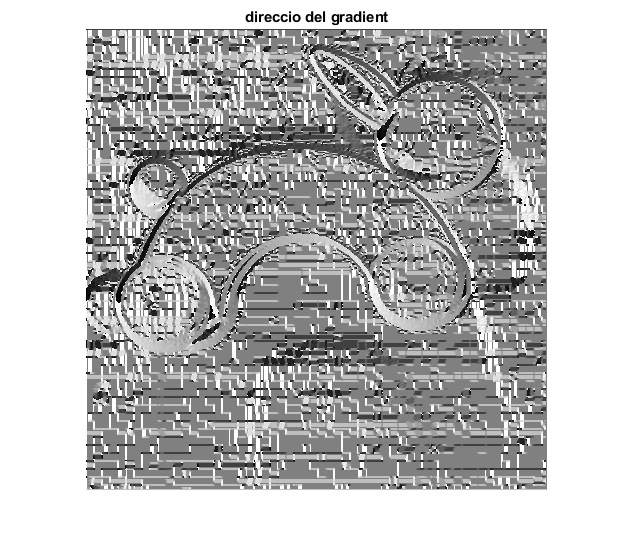

dir = dir+pi;
dir = dir/2/pi;
dir = uint8(255*dir);
imshow(dir), title('direccio del gradient')

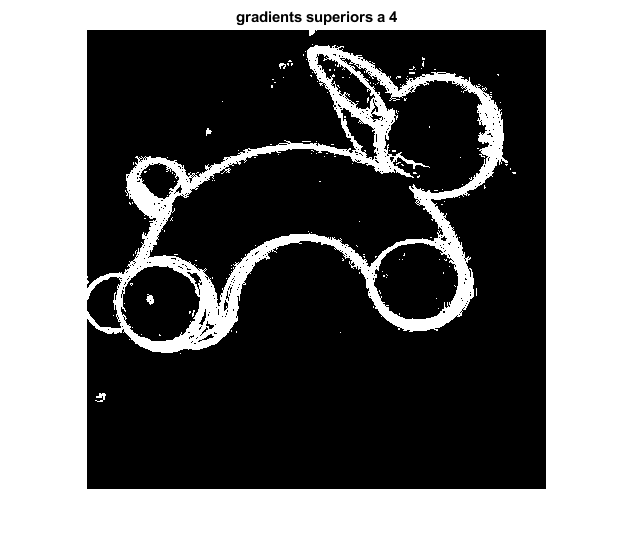

bons = (mod>4);
figure, imshow(bons), title('gradients superiors a 4')

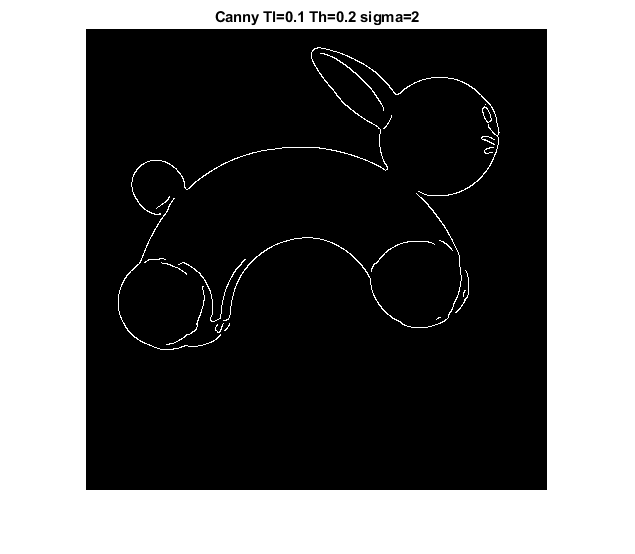

% utilització de l'operador de Canny
res = edge(im,'canny', [0.1 0.2], 2);
imshow(res), title('Canny Tl=0.1 Th=0.2 sigma=2')

Pruebas con los parámetros del operador de Canny

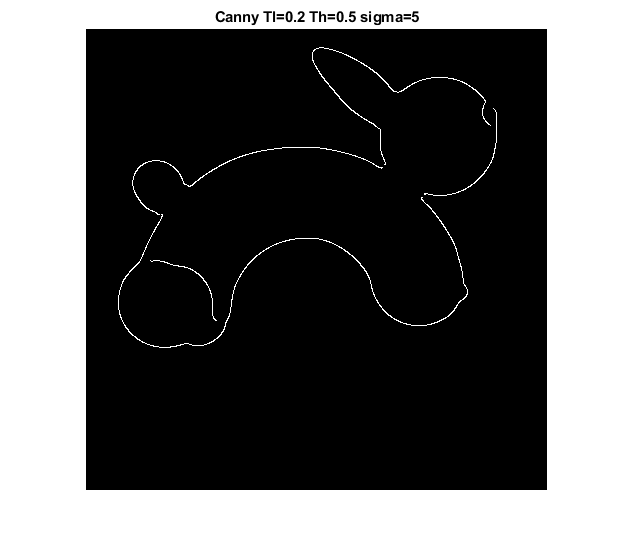

res = edge(im,'canny', [0.2 0.5], 5);
imshow(res), title('Canny Tl=0.2 Th=0.5 sigma=5')

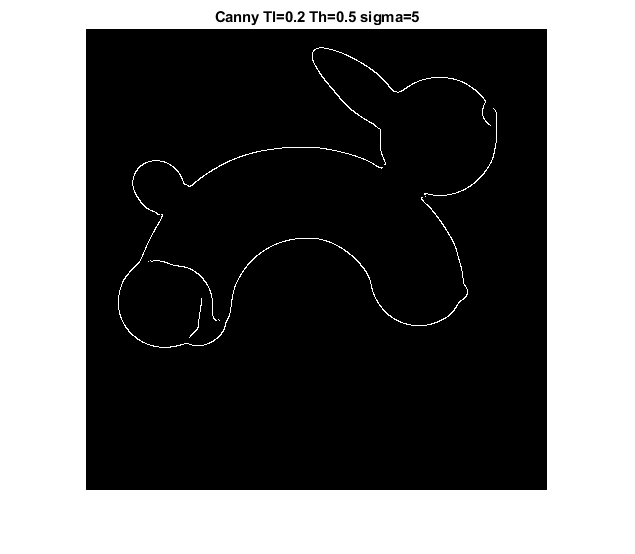


res = edge(im,'canny', [0.15 0.25], 5);
imshow(res), title('Canny Tl=0.15 Th=0.25 sigma=5')